# 回归分析画图

close all
clear
clc
load("statistical analysis\analysis-results-normalized.mat");


## 每项的参数

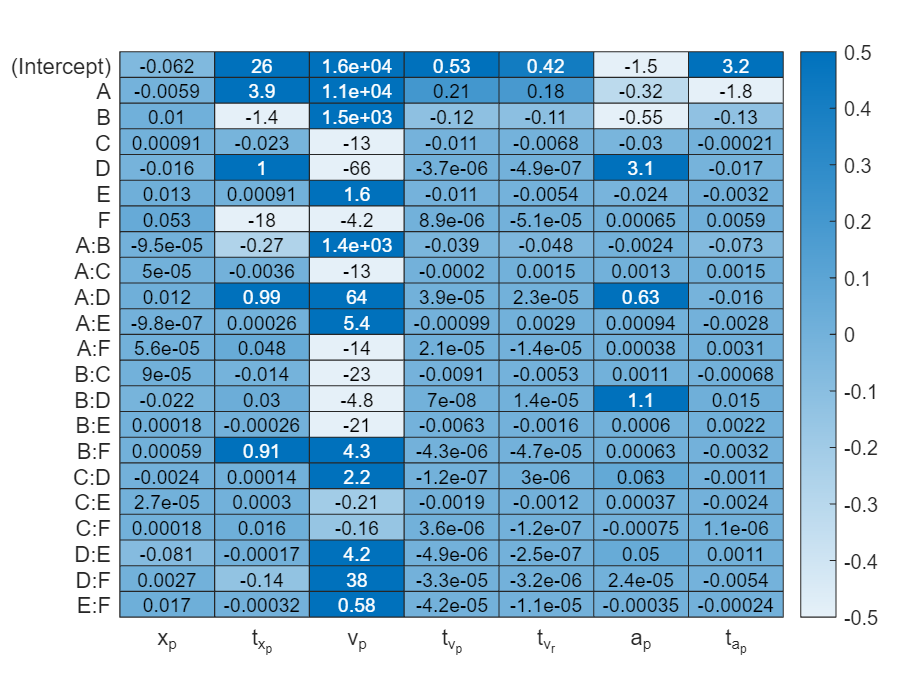

X = categorical({'x_p';'t_{x_p}';'v_p';'t_{v_p}';'t_{v_r}';'a_p';'t_{a_p}'},"Ordinal",true);
Y = categorical(lrmInter{1}.Formula.TermNames,"Ordinal",true);
interRegress_est = zeros(length(Y),7);
for ii = 1:size(lrmInter,1)
    interRegress_est(:,ii) = lrmInter{ii}.Coefficients.Estimate;
end
% figure;
% b3 = bar3(interRegress_est,0.8,"detached");
% set(gca,"XTickLabel",X);
% set(gca,"YTick",1:22,"YTickLabel",Y);
% % set(gca,'ZScale','log');
% % set(gca,"ZTickLabel",flip(get(gca,"ZTickLabel")));
% % colormap('sky');
% for k = 1:length(b3)
%     b3(k).CData = b3(k).ZData;
%     b3(k).FaceColor = 'interp';
%     b3(k).FaceAlpha = 0.75;
%     b3(k).LineWidth = 0.25;
%     % b3(k).EdgeLighting = "none";
% end
% colorbar;
figure('Units','centimeters');
h = heatmap(X,Y,interRegress_est,'ColorScaling','scaled');
h.CellLabelFormat = '%.2g';
% h.Colormap = flipud(h.Colormap);
h.ColorLimits = [-0.5,0.5];

% set(gca,'XAxisLocation','top');
% set(gcf,'OuterPosition',[0,0,19,6]);
% set(gca,'InnerPosition',[0,0,1,1]);
% set(gca,'FontName','Times New Roman','FontSize',8);

## 交互作用全项

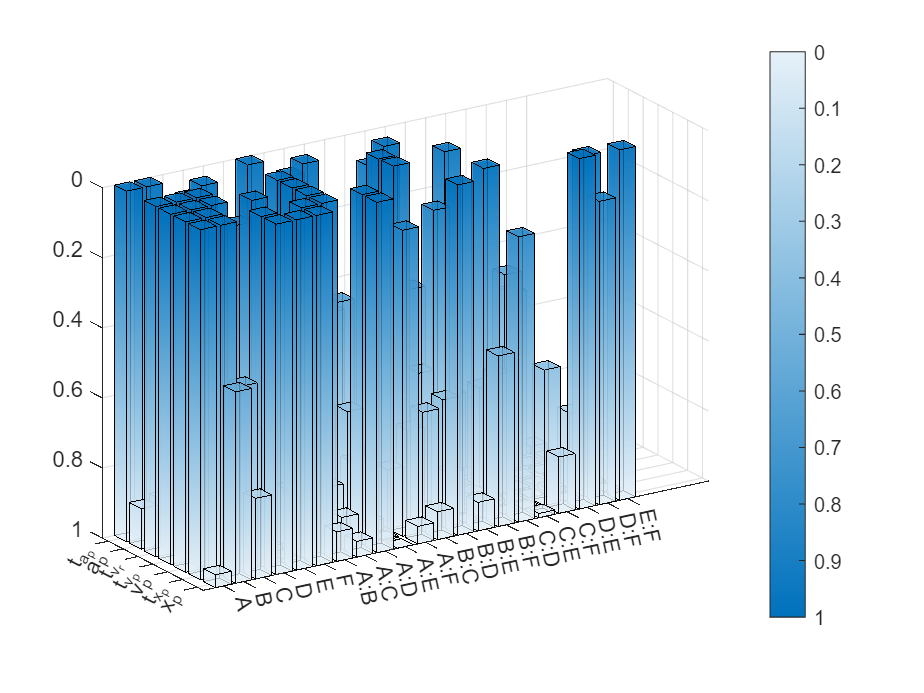

X = categorical({'x_p';'t_{x_p}';'v_p';'t_{v_p}';'t_{v_r}';'a_p';'t_{a_p}'},"Ordinal",true);
Y = categorical(lrmInter{1}.Formula.TermNames(2:end),"Ordinal",true);
interRegress_pValue = zeros(length(Y),7);
for ii = 1:size(lrmInter,1)
    interRegress_pValue(:,ii) = lrmInter{ii}.anova.pValue(1:end-1);
end
figure;
b3 = bar3(1 - interRegress_pValue,0.8,"detached");
set(gca,"XTickLabel",X);
set(gca,"YTick",1:21,"YTickLabel",Y);
set(gca,"ZTickLabel",flip(get(gca,"ZTickLabel")));
% set(gca,"XTickLabel",[],"YTickLabel",[],"ZTickLabel",[]);
% set(gca,"ZDir","reverse");
colormap('sky');
for k = 1:length(b3)
    b3(k).CData = b3(k).ZData;
    b3(k).FaceColor = 'interp';
    b3(k).FaceAlpha = 0.75;
    b3(k).LineWidth = 0.25;
    % b3(k).EdgeLighting = "none";
end
% ax = get(gca);
% tmp = ax.Colormap;
% set(gca,'Colormap',flipud(tmp));
cb = colorbar;
cb.YDir = 'reverse';
view([237.126 19.545])

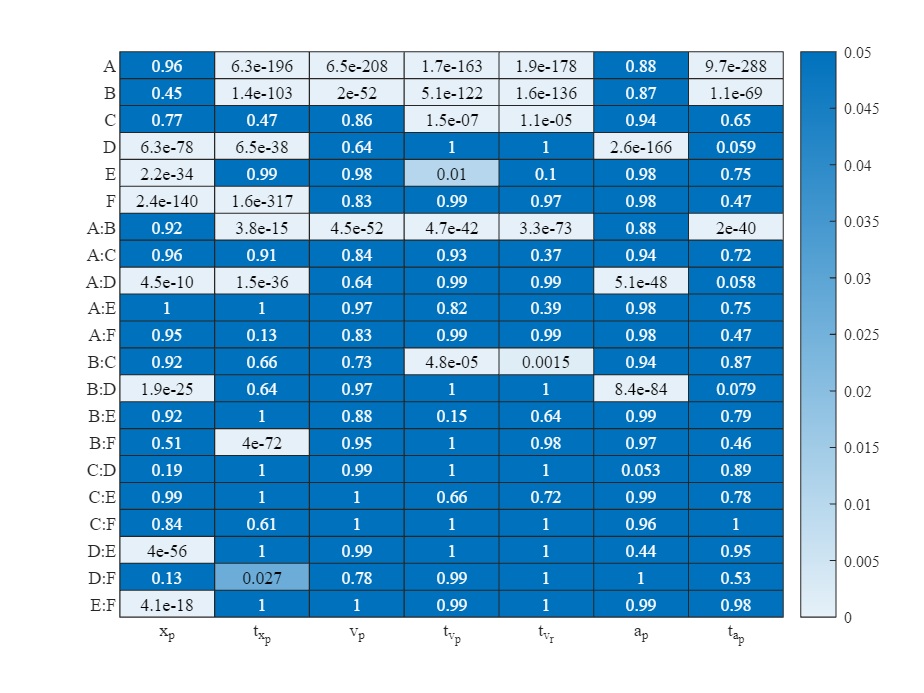


figure('Units','centimeters');
h = heatmap(X,Y,interRegress_pValue,'ColorScaling','scaled');
h.CellLabelFormat = '%.2g';
% h.Colormap = flipud(h.Colormap);
h.ColorLimits = [0,0.05];
% set(gcf,'OuterPosition',[0,0,19,6]);
% set(gca,'InnerPosition',[0,0,1,1]);
set(gca,'FontName','Times New Roman','FontSize',8);

% figure;
% ttt = interRegress_pValue < 0.05;
% heatmap(Y,X,double(ttt'),'ColorScaling','scaled','ColorbarVisible','off','CellLabelFormat','none');

## 主效应分析（不考虑交互项）

这里，我是用广义线性回归模型（含交互作用）拟合各数据，然后分别做anova分析（即F检验）

假设因素A没有主效应（即检验因素A下的所有样本都来自均值相等的总体），如果p值>α，则不能拒绝原假设即没有主效应；否则则有主效应（即p值越小主效应越明显）

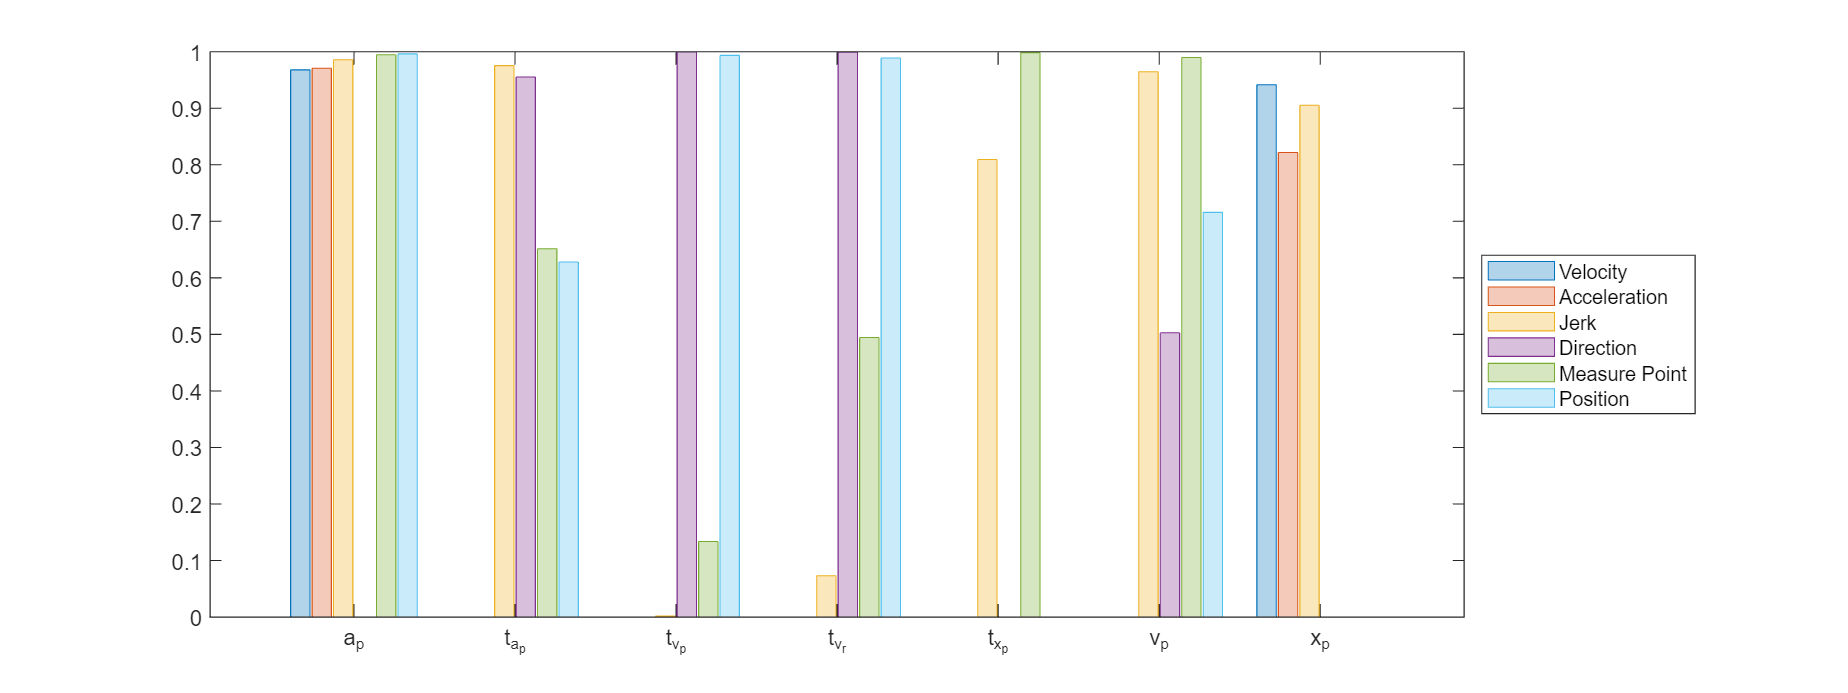


X = categorical({'x_p';'t_{x_p}';'v_p';'t_{v_p}';'t_{v_r}';'a_p';'t_{a_p}'},"Ordinal",true);
Y = categorical({'Velocity','Acceleration','Jerk','Direction','Measure Point','Position'},"Ordinal",true);
linearRegress_pValue = zeros(length(Y),7);
for ii = 1:size(lrmLinear,1)
    linearRegress_pValue(:,ii) = lrmLinear{ii}.anova.pValue(1:6);
end
fig = figure;
figPos = get(gcf,"Position");
set(gcf,"Position",[figPos(1),figPos(2),figPos(3)*2,figPos(4)]);
b = bar(X,linearRegress_pValue,0.9,"EdgeColor","flat","FaceAlpha",0.3);
legend(Y,"Location","eastoutside");

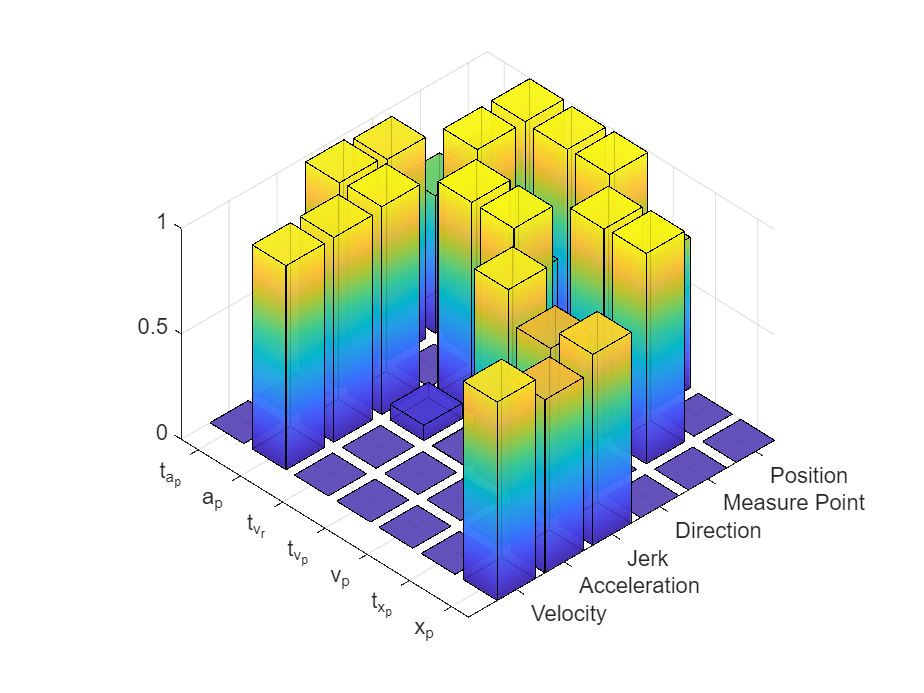

figure;
b3 = bar3(linearRegress_pValue,0.8,"detached");
set(gca,"XTickLabel",X);
set(gca,"YTickLabel",Y);
for k = 1:length(b3)
    zdata = b3(k).ZData;
    b3(k).CData = zdata;
    b3(k).FaceColor = 'interp';
    b3(k).FaceAlpha = 0.8;
    % b3(k).EdgeLighting = "none";
end
colormap('parula')
view([225.994 36.732])

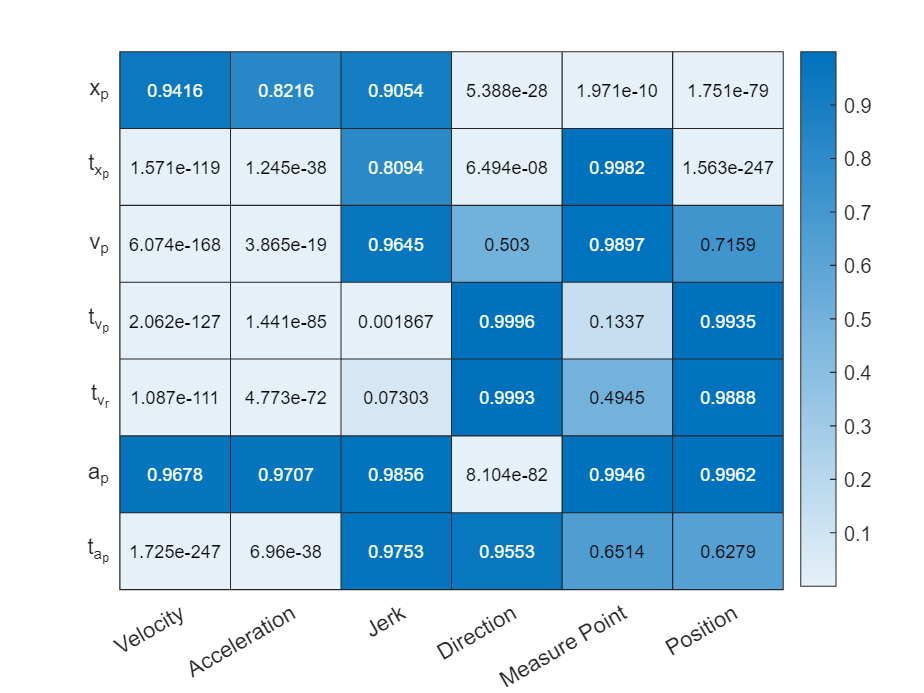

figure;
h = heatmap(Y,X,linearRegress_pValue','ColorScaling','scaled');